%Video Sampling
videoFileName = "data/traffic_sample3.mp4";

videoSource = VideoReader(videoFileName);

fprintf('Video Resolution: %d x %d pixels\n', videoSource.Width, videoSource.Height);

Video Resolution: 1920 x 1080 pixels


fprintf('Frame Rate: %.2f Hz (Temporal Sampling Rate)\n', videoSource.FrameRate);

Frame Rate: 30.00 Hz (Temporal Sampling Rate)


fprintf('Total Frames: %d\n', videoSource.NumFrames);

Total Frames: 1699


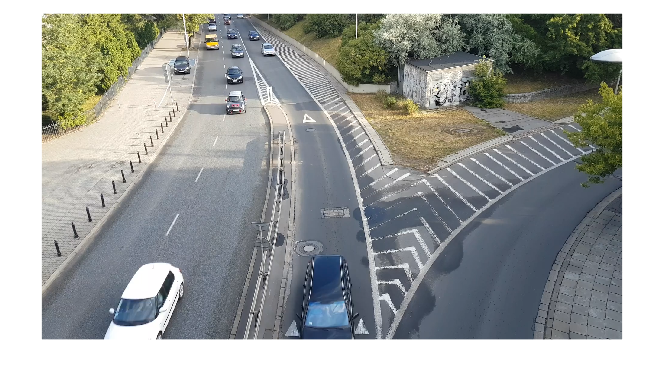


firstFrame = readFrame(videoSource);
imshow(firstFrame);

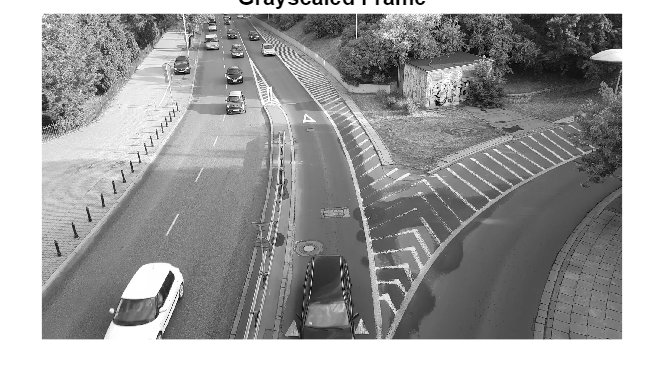

%Gray Scaling
grayFrame =rgb2gray(firstFrame);
grayFrame = im2double(grayFrame);
imshow(grayFrame); 
title('Grayscaled Frame');

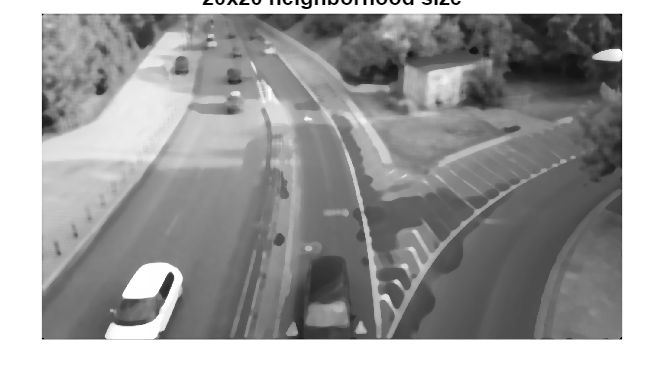

%Median Filtering
filteredFrame20 = medfilt2(grayFrame, [20 20]);
filteredFrame = medfilt2(grayFrame, [3 3]);
figure; imshow(filteredFrame20);title("20x20 neighborhood size");

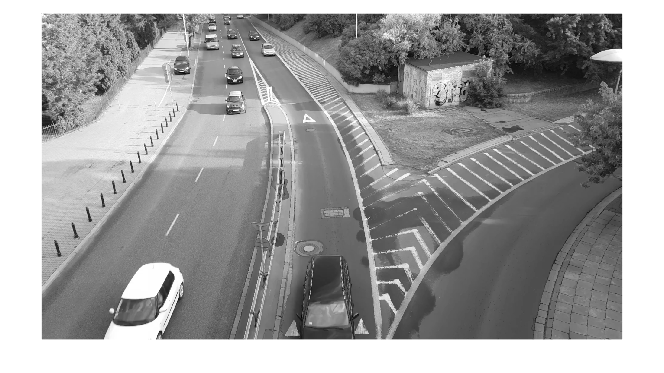

figure;imshow(filteredFrame);

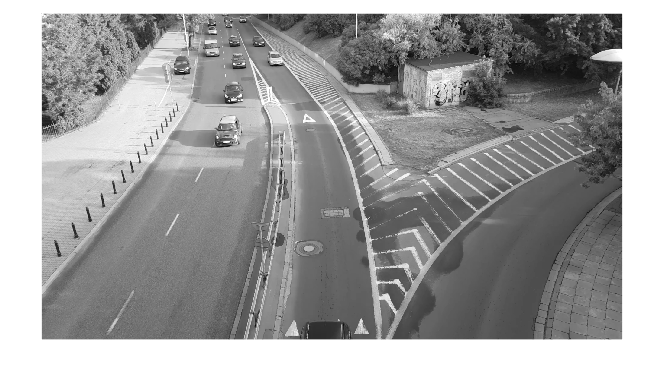

%Frame at second:0.5
videoSource.CurrentTime = 0.5; 
bgFrame = readFrame(videoSource);
bgGray = im2double(rgb2gray(bgFrame));
bgFiltered = medfilt2(bgGray, [3 3]); 

%Frame at second:0.7
videoSource.CurrentTime = 0.7; 
currFrame = readFrame(videoSource);
currGray = im2double(rgb2gray(currFrame));
currFiltered = medfilt2(currGray, [3 3]); 
%Temporal Substraction

diffSignal_t = abs(currFiltered - bgFiltered);

%Visualization Of Signals
figure;
imshow(bgFiltered); 

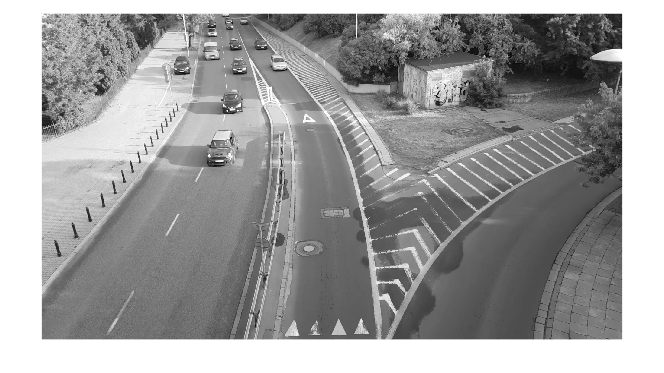


figure;
imshow(currFiltered); 

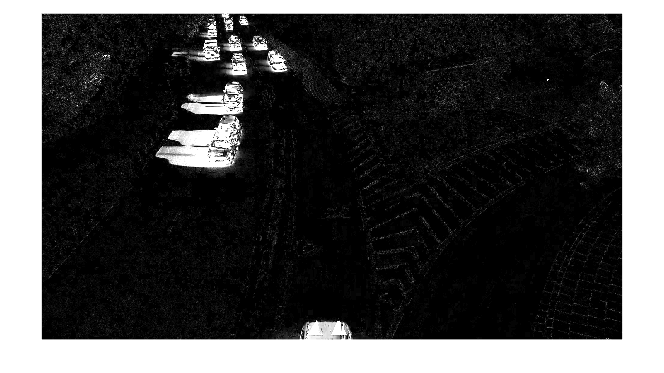



figure;
imshow(diffSignal_t * 5);

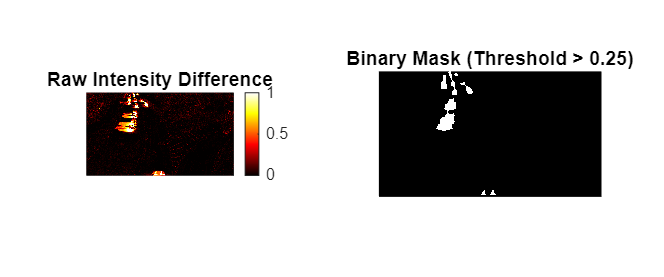

% --- VISUALIZING MASKING & SHADOW REJECTION ---

motionMask = diffSignal_t > 0.25; 

% 2. Clean the mask for visualization
cleanMask = imopen(motionMask, strel('disk', 1));
cleanMask = imclose(cleanMask, strel('disk', 15));

figure('Name', 'The Masking Process', 'Position', [100, 100, 1200, 500]);
subplot(1,2,1); 
imshow(diffSignal_t * 3); 
%Heatmap for intensity visualization
colormap(gca, 'hot');   
title('Raw Intensity Difference');
colorbar;

subplot(1,2,2); 
imshow(cleanMask); 
title(['Binary Mask (Threshold > 0.25)']);

videoFileName = "data/traffic_sample3.mp4";
videoSource = VideoReader(videoFileName);
videoSource.CurrentTime = 0;
firstFrame = readFrame(videoSource);

backgroundModel = im2double(rgb2gray(firstFrame));
backgroundModel = medfilt2(backgroundModel, [3 3]);

alpha = 0.05;         
thresholdValue = 0.20;
videoPlayer = vision.VideoPlayer('Name', 'Real-Time Detection');
while hasFrame(videoSource)
    colorFrame = readFrame(videoSource);

    grayFrame = im2double(rgb2gray(colorFrame));
    %filter the frame
    conditionedSignal = medfilt2(grayFrame, [3 3]);
    %take difference
    diffSignal = abs(conditionedSignal - backgroundModel);
    %Update model
    backgroundModel = (1 - alpha) * backgroundModel + alpha * conditionedSignal;
    
    motionMask = diffSignal > thresholdValue;
    cleanMask = imopen(motionMask, strel('disk', 1));
    cleanMask = imclose(cleanMask, strel('disk', 10));
    
    stats = regionprops(cleanMask, 'BoundingBox', 'Area');
    
    outFrame = colorFrame;
    for i = 1:length(stats)
        if stats(i).Area > 300
            outFrame = insertShape(outFrame, 'Rectangle', stats(i).BoundingBox, ...
                                   'Color', 'green', 'LineWidth', 3);
        end
    end

    step(videoPlayer,outFrame);
end
release(videoPlayer);


% --- VISUALIZING TEMPORAL SAMPLING & MOTION ALIASING ---

% 1. Set the initial Reference Frame B(x,y,t_0)
videoSource.CurrentTime = 1.0; 
refFrame = im2double(rgb2gray(readFrame(videoSource)));

% 2. HIGH TEMPORAL SAMPLING (Close in time)
% Sample the very next frame (e.g., 1/30th of a second later)
frameFast = im2double(rgb2gray(readFrame(videoSource)));
diffFast = abs(frameFast - refFrame);

% 3. LOW TEMPORAL SAMPLING (Farther in time)
% Jump ahead by 1.5 seconds (simulating a very low frame rate)
videoSource.CurrentTime = 2.5; 
frameSlow = im2double(rgb2gray(readFrame(videoSource)));
diffSlow = abs(frameSlow - refFrame);

% --- VISUALIZATION ---
figure('Position', [50, 50, 1000, 400]);

subplot(1,2,1); imshow(diffFast * 5);
title('High Sampling Rate: Small Temporal Step');
xlabel('Motion is fluid and localized');

subplot(1,2,2); imshow(diffSlow * 5);
title('Low Sampling Rate: Large Temporal Step');
xlabel('Motion is disjointed (Aliasing potential)');